% 9 hz center row 9 canopy elements, consider the buoyancy force

ForceB9Center = [0.00796219,0.00908807,0.00433309,0.00280036,0.00200288,0.00132192,0.000956794,0.000799083,0.000747537];
ForceB6Center = [0.00377081,0.00428969,0.00203604,0.00107832,0.00073077,0.000504983,0.000354169,0.000310929,0.000304365];
ForceB12Center = [0.013371,0.0142791,0.0078505,0.00572974,0.00402537,0.00268153,0.00195357,0.00158374,0.00142877];

% 9 hz center row 9 canopy elements, without consider the buoyancy force

ForceWB9Center = [0.00728497,0.00831948,0.00395613,0.00255419,0.00182626,0.00120506,0.000872264,0.000728403,0.000681401];
ForceWB6Center = [0.00344078,0.00391324,0.00185649,0.00098294,0.000666096,0.000460264,0.000322835,0.000283407,0.000277399];
ForceWB12Center = [0.0122948,0.0131348,0.00718781,0.00523478,0.00367348,0.00244517,0.00178145,0.00144373,0.00130244];

% 9 hz nearest row 9 canopy elements, without consider the buoyancy force

ForceB6nearest = [0.00522717,0.00363913,0.00159895,0.00149992,0.00124054,0.000985648,0.0010236,0.00102242,0.000986181];
ForceB9nearest = [0.0101124,0.00701823,0.00329245,0.00294483,0.00216897,0.00157587,0.00149487,0.00147579,0.00140393];
ForceB12nearest = [0.016198,0.0118879,0.00615563,0.00521583,0.00364528,0.00262377,0.00229254,0.00220355,0.00209619];

% 9 hz nearest row 9 canopy elements, consider the buoyancy force

ForceWB6nearest = [0.00477582,0.0033228,0.00145894,0.00136926,0.0011327,0.000899278,0.000935593,0.000933973,0.000901334];
ForceWB9nearest = [0.00926448,0.00641788,0.00300605,0.0026884,0.00198029,0.00143764,0.00136603,0.001348,0.00128311];
ForceWB12nearest = [0.0149149,0.0109038,0.00562957,0.00476434,0.00332852,0.00239327,0.00209503,0.00201296,0.0019156];

h = figure(1)

h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 438 560 420]
       Units: 'pixels'

  Show all properties


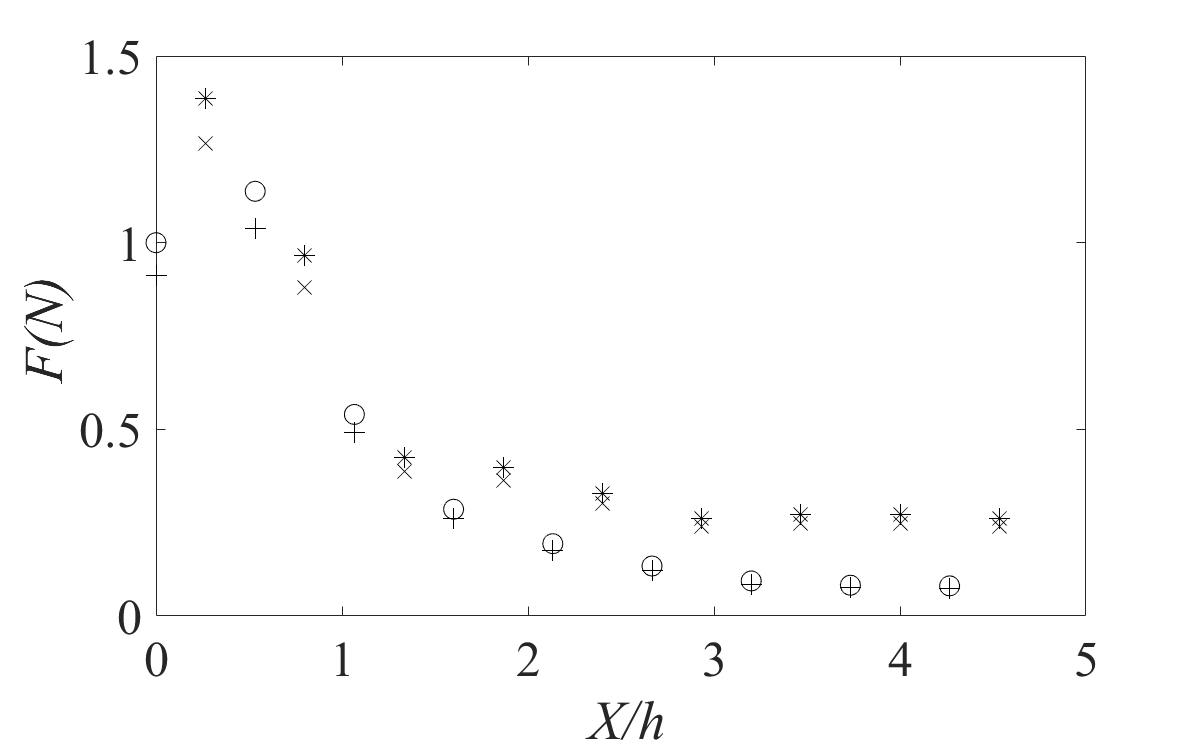

xnearest = [];
for i = 1:9
    xnearest = [xnearest, 10 + (i-1) * 20];
end
xcenter = [];
for i = 1:9
    xcenter = [xcenter, (i-1) * 20];
end
xcenter = xcenter/37.5;
xnearest = xnearest/37.5;
xintCenter = linspace(xcenter(1),xcenter(9),100);
xintNearest = linspace(xnearest(1),xnearest(9),100);
spl = spline(xcenter,ForceB9Center);
plot(xcenter,ForceB6Center/ForceB6Center(1),'o','color','black','MarkerSize',10);
hold on
plot(xcenter,ForceWB6Center/ForceB6Center(1),'+','color','black','MarkerSize',10);
hold on
plot(xnearest,ForceB6nearest/ForceB6Center(1), '*','color','black','MarkerSize',10);
hold on
plot(xnearest,ForceWB6nearest/ForceB6Center(1),'x','color','black','MarkerSize',10);
xlabel('{\it X/h}');
ylabel('{\it F(N)}');
set(h,'Position',[100, 100, 800, 500])
set(gca, 'FontName', 'Times New Roman')
set(gca, 'FontSize', 25)

legend('center P', 'ceter P_{equal')
legend('Center with {\it F_B}','Center without {\it F_B}', 'Nearest with {\it F_B}', 'Nearest without {\it F_B}');
legend boxoff 
